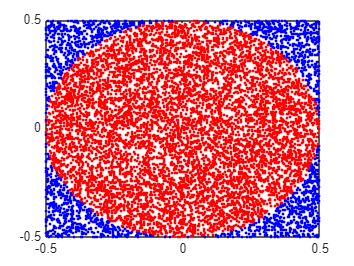

% This MATLAB code estimates the value of π (pi) using the Monte Carlo simulation method.
% The approach involves generating random points within a unit square and checking if they fall
% inside a quarter circle inscribed within that square. The ratio of points that fall inside the
% quarter circle to the total number of points generated is used to approximate the value of π.

% Clear the workspace and command window for a fresh start
clear
clc

% Initialize the counter for points that fall inside the quarter circle
inside = 0;

% Define the total number of random points to generate for the initial visualization
nmax = 10000;

% Generate random points and plot them
for n = 1:nmax
    % Generate a random x and y coordinate in the range [0, 1]
    x = rand; 
    y = rand;

    % Center the coordinates around (0, 0) for easier distance calculation
    x1 = x - 0.5; % Shift x to range [-0.5, 0.5]
    y1 = y - 0.5; % Shift y to range [-0.5, 0.5]

    % Check if the point (x1, y1) lies within the quarter circle of radius 0.5
    if sqrt(x1^2 + y1^2) <= 0.5
        % If the point is inside the quarter circle, plot it in red
        plot(x1, y1, 'r.'); 
        inside = inside + 1; % Increment the counter for points inside the circle
    else
        % If the point is outside the quarter circle, plot it in blue
        plot(x1, y1, 'b.'); 
    end

    hold on; % Retain the current plot when adding new points
end
hold off; % Release the hold on the current plot

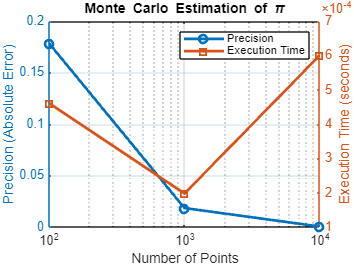


% Start measuring execution time
tic;

% Define an array of different numbers of points to test the estimation of π
numPointsArray = [1e2, 1e3, 1e4];
num_iterations = length(numPointsArray); % Get the number of different test cases

% Initialize arrays to store the estimated values of π and the execution times
pi_estimates = zeros(1, num_iterations); 
executionTimes = zeros(1, num_iterations); 

% Loop over the different numbers of points specified in numPointsArray
for i = 1:num_iterations
    numPoints = numPointsArray(i); % Get the current number of points to generate
    
    % Start timing the execution of the simulation
    tic; 
    
    % Generate random points for the current iteration
    x = rand(1, numPoints); % Generate an array of random x coordinates
    y = rand(1, numPoints); % Generate an array of random y coordinates
    
    % Calculate the number of points that fall inside the quarter circle
    % A point (x, y) is inside the quarter circle if x^2 + y^2 <= 1
    numInsideCircle = sum(x.^2 + y.^2 <= 1); 
    
    % Estimate the value of π using the ratio of points inside the circle
    % The area of the quarter circle is (π * r^2) / 4 and the area of the unit square is 1.
    % Thus, π can be estimated as (points inside circle / total points) * 4
    pi_estimates(i) = (numInsideCircle / numPoints) * 4; 
    
    % Stop timing and record the execution time
    executionTimes(i) = toc; 
end

% Calculate the precision of the π estimates by comparing to the true value of π
truePi = pi; % MATLAB's built-in constant for π
precision = abs(pi_estimates - truePi); % Calculate the absolute error

% Plot the precision of the π estimates against the number of points used
figure;
yyaxis left; % Create a dual-axis plot
plot(numPointsArray, precision, '-o', 'LineWidth', 2); % Plot precision
xlabel('Number of Points'); % Label for x-axis
ylabel('Precision (Absolute Error)'); % Label for left y-axis
set(gca, 'XScale', 'log'); % Set x-axis to logarithmic scale
title('Monte Carlo Estimation of \pi'); % Title for the plot

yyaxis right; % Switch to the right y-axis
plot(numPointsArray, executionTimes, '-s', 'LineWidth', 2); % Plot execution time
ylabel('Execution Time (seconds)'); % Label for right y-axis
legend('Precision', 'Execution Time'); % Legend for the plot
grid on; % Enable grid for better readability

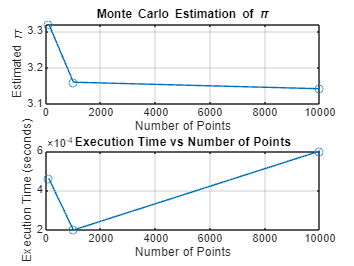


% Plot the estimated values of π and execution times in separate subplots
figure;
subplot(2, 1, 1); % Create a subplot for the estimated values
plot(numPointsArray, pi_estimates, '-o'); % Plot estimated π values
xlabel('Number of Points'); % x-axis label
ylabel('Estimated \pi'); % y-axis label
title('Monte Carlo Estimation of \pi'); % Title for the subplot
grid on; % Enable grid

subplot(2, 1, 2); % Create a subplot for execution times
plot(numPointsArray, executionTimes, '-o'); % Plot execution times
xlabel('Number of Points'); % x-axis label
ylabel('Execution Time (seconds)'); % y-axis label
title('Execution Time vs Number of Points'); % Title for the subplot
grid on; % Enable grid


% Display the results of the estimation for each number of points
for i = 1:num_iterations
    fprintf('Points: %d, Estimated Pi: %.5f, Time: %.5f seconds\n', ...
        numPointsArray(i), pi_estimates(i), executionTimes(i)); % Print results
end

Points: 100, Estimated Pi: 3.32000, Time: 0.00046 seconds
Points: 1000, Estimated Pi: 3.16000, Time: 0.00020 seconds
Points: 10000, Estimated Pi: 3.14200, Time: 0.00060 seconds



toc; % Stop timing the entire execution

Elapsed time is 0.702461 seconds.


fprintf('The approximated pi is equal to %f\n', pi_estimates(3)); % Display the final approximation of π

The approximated pi is equal to 3.142000
